# Homework 1 (Solution) 

Math 3607

Summer 2021

Tae Eun Kim

## Problem 1 (Gap of 10)

The key point of this problem lies in simulating the tossing of a biased coin with the following probability profile: $P(H) = 1/4$ (heads) and $P(T) = 3/4$ (tails). Let's use 0 for tails and 1 for heads. I will show couple ways.

**Using **`randi:`

toss = randi([0 3]);
if toss > 0
    toss = 1;
end
toss

toss = 1

**Using **`rand:`

toss = floor( rand() + 0.25 )

toss = 0

Why does it work? The expression `rand() + 0.25`  generates a number in $(0.25, 1.25)$ with equal likelihood. So numbers in the interval $(0.25, 1)$ are three times more likely to appear than those from $[1, 1.25)$. The `floor` function maps numbers in $(0.25, 1)$ to 0 and those in $[1, 1.25)$ to 1, successfully simulating the tossing of a bias coin with the given description. 

It is not known in advance how many tosses are needed until the gap reached 10. So use a `while`-loop:

nTosses = 0;  % number of tosses
nHeads = 0;   % number of heads
nTails = 0;   % number of tails
while abs(nHeads-nTails) < 10
    toss = floor( rand() + 0.25 );
    if toss == 0
        nTails = nTails + 1;
    else
        nHeads = nHeads + 1;
    end
    nTosses = nTosses + 1;
end
fprintf('The gap reached 10 with %d tosses.\n', nTosses)

The gap reached 10 with 12 tosses.


**Note.** The code above suffices. However, if you want to repeat the simulation multiple times and to monitor how many tosses are needed till the gap reaches 10. You will need an additional (outer loop) to embrace the `while`-loop written above. For example:

nGames = 10; % number of games played
result = zeros(nGames, 1); 
% initialize a vector to record the number of tosses
% to reach the gap of 10.

for j = 1:nGames
    nTosses = 0;  % number of tosses
    nHeads = 0;   % number of heads
    nTails = 0;   % number of tails
    while abs(nHeads-nTails) < 10
        toss = floor( rand() + 0.25 );
        if toss == 0
            nTails = nTails + 1;
        else
            nHeads = nHeads + 1;
        end
        nTosses = nTosses + 1;
    end
    %fprintf('The gap reached 10 with %d tosses.\n', nTosses)
    result(j) = nTosses;
end

To view how many tosses were needed for all games, simply type

result

result =     22
    16
    18
    10
    50
    18
    10
    14
    24
    24


To find out the average number of tosses till the gap reaches 10, do

mean(result)

ans = 20.6000

## Problem 2 (Convergence of Sequences)

We will take the value of `pi` stored in MATLAB as the true value of $\pi$. As a prep work, suppose that `n` is given. We will concentrate first on calculating $a_n$ and $b_n$. Using a `for`-loop, we can form these terms as below:

format long g
n = 10;
a_n = 0; b_n = 0;
for k = 0:n
    a_n = a_n + 6/sqrt(3)*(-1/3)^k / (2*k+1);
    b_n = b_n + 16/5*(-1/25)^k / (2*k+1) - 4/239*(-1/239^2)^k / (2*k+1);
end
a_n

a_n =           3.14159330450308

b_n

b_n =           3.14159265358979

As the last lines show, with only $n = 10$, they are already quite close to $\pi$. 

Now that the key part of the problem has been solve, let's design an outer loop which calculates terms $a_0, a_1, \ldots$ until it is close enough to $\pi$. (One may avoid the use of the inner for-loop, but I will present this slightly verbose version for the sake of instruction.) The given *tolerance* is $10^{-6}$. 

tol = 1e-6;
nMax = 100;    % maximum number of iterations
n = 0;
% fprintf('%2s %16s %16s\n', 'n', 'a_n', '|a_n - pi|');
% fprintf('%36s', repmat('-', 1, 36))
while n == 0 || (errAbs > tol && n <= nMax)
    a = 0;
    for k = 0:n
        a = a + (-1/3)^k / (2*k+1);
    end
    a = 6/sqrt(3)*a;   % since 6/sqrt(3) is a common factor.
    errAbs = abs(a - pi);
    fprintf('%2d %16.8f %16.8e\n', n, a, errAbs)
    n = n + 1;
end

 0       3.46410162   3.22508962e-01
 1       3.07920144   6.23912179e-02
 2       3.15618147   1.45888180e-02
 3       3.13785289   3.73976199e-03
 4       3.14260475   1.01209207e-03
 5       3.14130879   2.83868127e-04
 6       3.14167431   8.16591090e-05
 7       3.14156872   2.39376480e-05
 8       3.14159977   7.12022171e-06
 9       3.14159051   2.14265171e-06
10       3.14159330   6.50913289e-07


**Note.** Before the beginning of the `while`-loop, the variable `errAbs` was not initialized and so the loop would not be initated if it were not for `n==0` preceding `(errAbs ... )`. An alternate method that is commonly used is to begin with

You handle $b_n$'s in the same fashion.

tol = 1e-6;
nMax = 100;    % maximum number of iterations
n = 0;
% fprintf('%2s %16s %16s\n', 'n', 'b_n', '|b_n - pi|');
% fprintf('%36s', repmat('-', 1, 36))
while n == 0 || (errAbs > tol && n <= nMax)
    b1 = 0; b2 = 0;
    for k = 0:n
        b1 = b1 + (-1/25)^k/(2*k+1);
        b2 = b2 + (-1/239^2)^k/(2*k+1);
    end
    b = 16/5*b1 - 4/239*b2;
    errAbs = abs(b - pi);
    fprintf('%2d %16.8f %16.8e\n', n, b, errAbs)
    n = n + 1;
end

 0       3.18326360   4.16709447e-02
 1       3.14059703   9.95624264e-04
 2       3.14162103   2.83757352e-05
 3       3.14159177   8.81407615e-07


The two numerical experiments provide an evidence that the sequence $b_n$ may converge to $\pi$ much quicker than $a_n$. 

## Problem 3 (Birthday Problem)

(a) Since we ignore a leap year, the probability $p$ for the group of $n$ people to have no match in birthdays is

$\displaystyle p = \frac{365}{365} \cdot \frac{364}{365} \cdots \frac{365-n+1}{365} = \prod_{j=0}^{n-1} \frac{365-j}{365}$.

and so the probability $q$ to have at least on birthday match is

$q = 1- p$.

(b) For a single instance, following the hints provided on p. 104, we write

n = 30;
nrs =  randi(365, 1, n);
nrs = sort(nrs);
d_nrs = diff(nrs);
id_nrs = find(d_nrs == 0);
nr_matches = length(id_nrs)

nr_matches =      1

(c) For multiple simulations (I will just use 10000 for demo here):

%% simulations
nr_sims = 1e4;
Nrs = randi(365, n, nr_sims);
Nrs = sort(Nrs);
D_Nrs = diff(Nrs);

Match = zeros(size(D_Nrs));    % preallocate: Match = 0 for no match
iD_Nrs = find(D_Nrs == 0 );    %              Match = 1 for a match
Match(iD_Nrs) = 1;
matches = sum(Match);
i_matches = find(matches > 0);
ratio_num = length(i_matches)/nr_sims;
ratio_ext = 1 - prod((365 - (0:n-1))./365);
disp('--------------------------------------')

--------------------------------------


disp(['fraction of matches (numeric):  ', num2str(ratio_num, 4)])

fraction of matches (numeric):  0.7028


disp(['fraction of matches (analytic): ', num2str(ratio_ext, 4)])

fraction of matches (analytic): 0.7063


In this script, `ratio_num` is a numerical approximation of the probability $q$ to have at least one match based on the result of simulations; `ratio_ext` is the exact probability computed in part (a). They appear to be in a reasonably good agreement.

## Problem 4 (Spiral Polygons)

The underlying geometry/mathematics of the problem and line-by-line explanation of the base code are found in Lecture 5 and Exam 1 Review videos. 

(a) The modified code (as a function) is included at the end of this document. 

(b) Running the given statements:

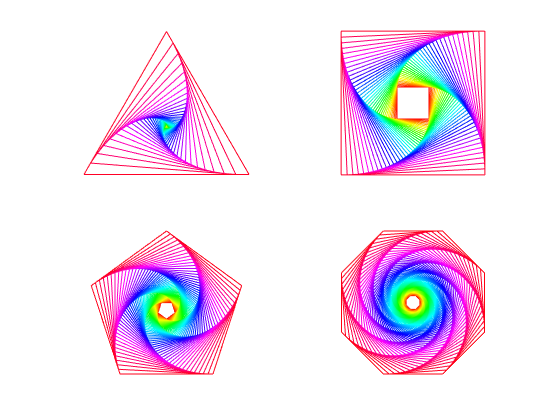

 clf
 subplot(2, 2, 1), spiralgon(3, 41, 4.5, -90);
 subplot(2, 2, 2), spiralgon(4, 37, -2.5, 45);
 subplot(2, 2, 3), spiralgon(5, 61, 3, -90);
 subplot(2, 2, 4), spiralgon(8, 91, -4, 22.5);

## Functions Used

### `spiralgon.m` 

 function V = spiralgon(n, m, d_angle, d_rot)
 % SPIRALGON plots spiraling regular n-gons
 % input:   n = the number of vertices
 %          m = the number of regular n-gons
 %          d_angle = the degree angle between successive n-gons
 %          (can be positive or negative)
 %          d_rot = the degree angle by which the innermost n-gon
 %                  is rotated
 % output:  V = the vertices of the outermost n-gon
 th = linspace(0, 360, n+1) + d_rot;
 V = [cosd(th);
     sind(th)];
 C = colormap(hsv(m));
 scale = sind(90 + 180/n - abs(d_angle))/...
     sind(90 - 180/n);
 R = [cosd(d_angle) -sind(d_angle);
     sind(d_angle) cosd(d_angle)];
 hold off
 for i = 1:m
     if i > 1
         V = scale*R*V;
     end
     plot(V(1,:), V(2,:), 'Color', C(i,:))
     hold on
 end
 set(gcf, 'Color', 'w')
 axis equal, axis off
 end